% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 2048;
Ny = 2048;

% Condiciones de Muestreo
dx =6.513*mm/Nx;
dy = dx;

lambda = 633*nm;
k=(2*pi)/lambda;

distPropagacion=73*mm;

zlim=Nx*dx^2/lambda; %Se decide usar Transformada de fresnel

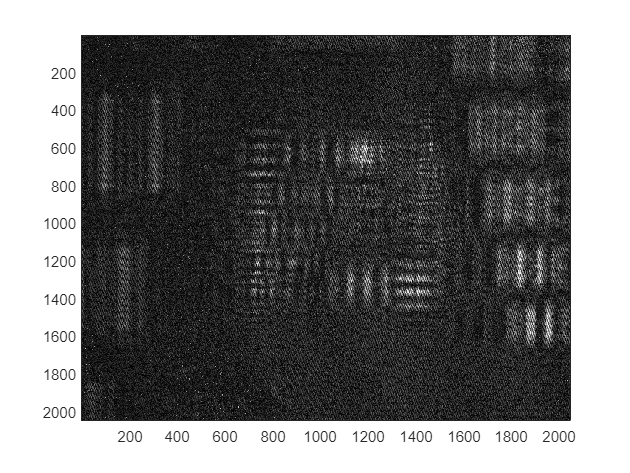


%Leer la imagen del holograma
ImHolo=imread("Hologram.tiff");%Pixeles de 2048*2048
%ImHolo=imresize(ImHolo,1);
%ImHolo=double(ImHolo);
%prom = mean2(ImHolo);
%ImSinMedia = ImHolo;
imagesc(ImHolo)
colormap("gray");

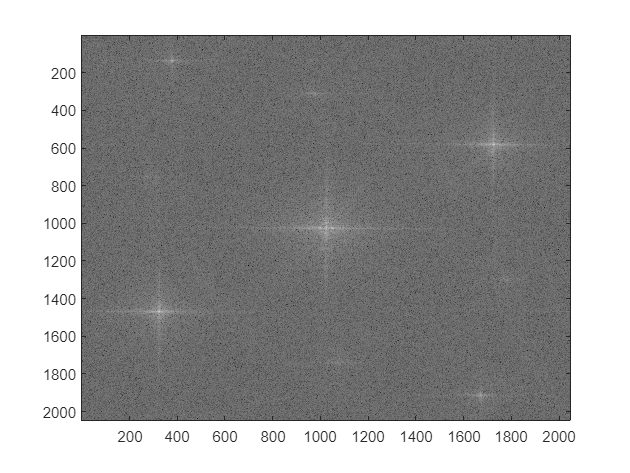

%Sacar transformada de Fourier del holograma
%FourierTransform=fft2(ImHolo);
FFTHOLO = (fftshift(fft2(ImHolo)));
imagesc(log(abs(FFTHOLO)));


% Se sacan los máximos
[maximosY,maximosX] = find(abs(FFTHOLO) == max(abs(FFTHOLO),[],"all"))

maximosY = 1025

maximosX = 1025

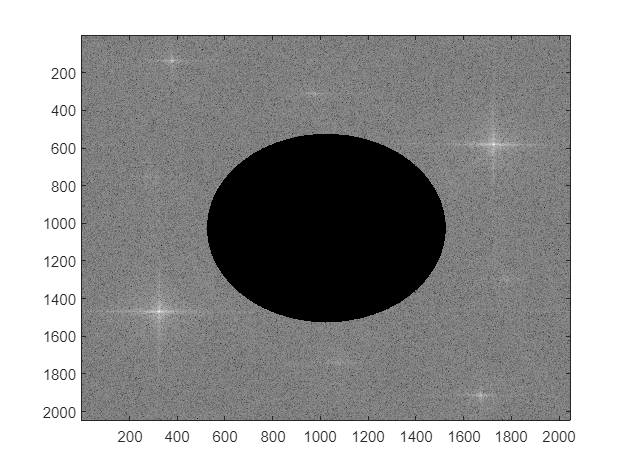


%Como el máximo central es el de mayor intensidad se elimina con un filtro para buscar los otros dos máximos
% 
FFTHoloSinCentro = FFTHOLO.*(~filtroCircular([1025 1025],500,size(FFTHOLO)));
imagesc(log10(abs(FFTHoloSinCentro)))

 %Deben encontrarse los dos máximos que dan cuenta de la información del objeto y onda de referencia

[maximosY1,maximosX1] = find(abs(FFTHoloSinCentro) == max(abs(FFTHoloSinCentro),[],"all"))

maximosY1 =         1469
         581


maximosX1 =          324
        1726


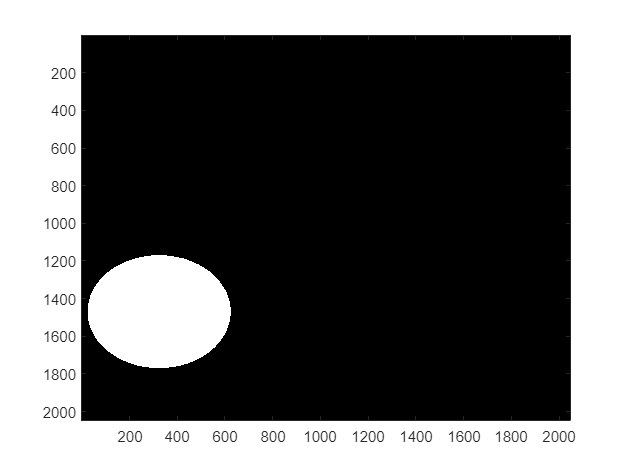

 %Creación de la máscara para la selección de un orden

Mascara1= (filtroCircular([324 1469],300,size(FFTHOLO)));
imagesc(Mascara1);

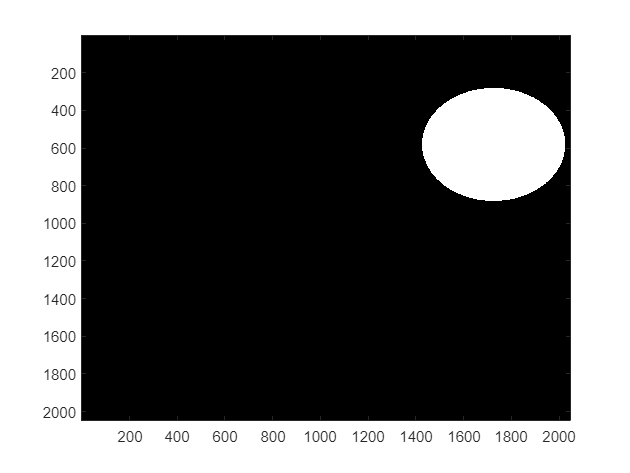

%Creación de máscara para selección de orden menos1
Mascara2= (filtroCircular([1726 581],300,size(FFTHOLO)));
imagesc(Mascara2);

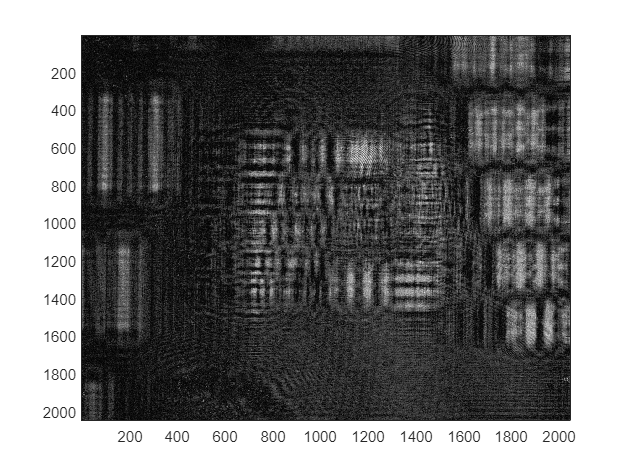

%Multiplicación máscara para orden menos 1
OrdenMenos=FFTHOLO.*Mascara2;
IFFTOrdenMenos=(ifft2(OrdenMenos));
imagesc(abs(IFFTOrdenMenos));

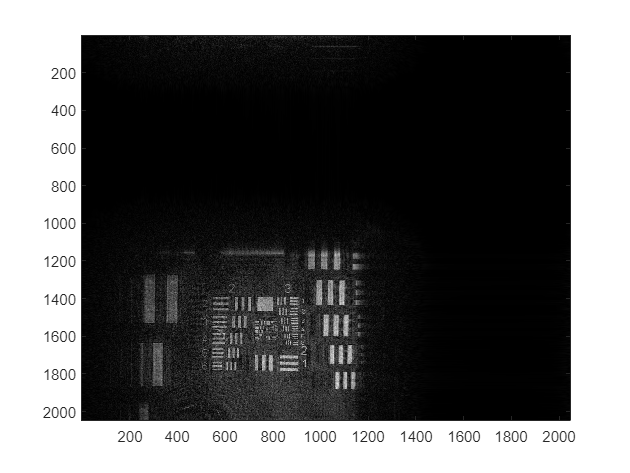

PropOrdenMenos=transformadaFresnel(IFFTOrdenMenos,dx,dy,distPropagacion, lambda);
imagesc(abs(PropOrdenMenos))

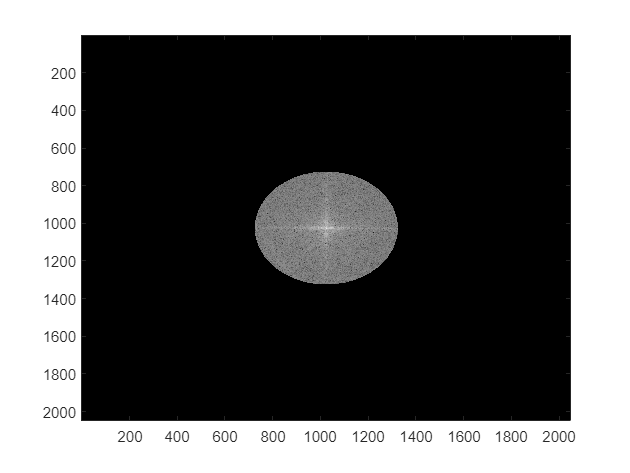

%Translación de orden menos al centro
OrdenMenosCentrado = imtranslate(OrdenMenos,[1025-1726, 1025-581],'FillValues',0);
imagesc(log(abs(OrdenMenosCentrado)))

IFFTCentroOrdenMenos=(ifft2(OrdenMenosCentrado));
imagesc(abs(IFFTCentroOrdenMenos))

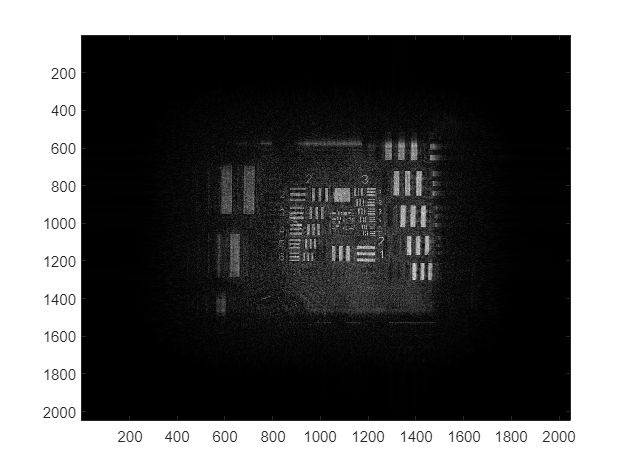

PropCentroOrdenMenos=fftshift(transformadaFresnel(IFFTCentroOrdenMenos,dx,dy,distPropagacion, lambda));
imagesc(abs((PropCentroOrdenMenos)))

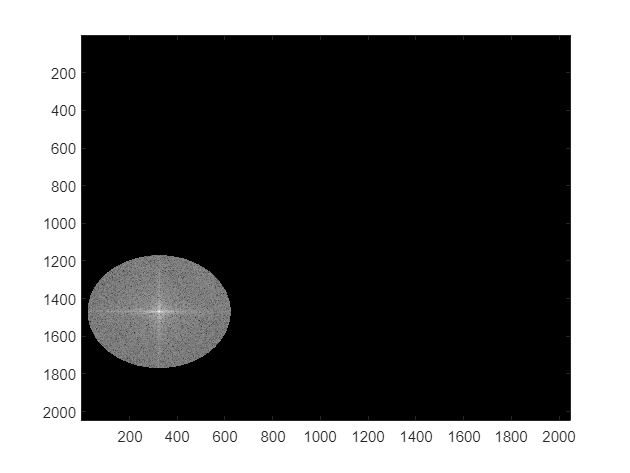

%Multiplicación con la máscara para obtener imagen virtual
OrdenMas=FFTHOLO.*Mascara1;
imagesc(log(abs((OrdenMas))))

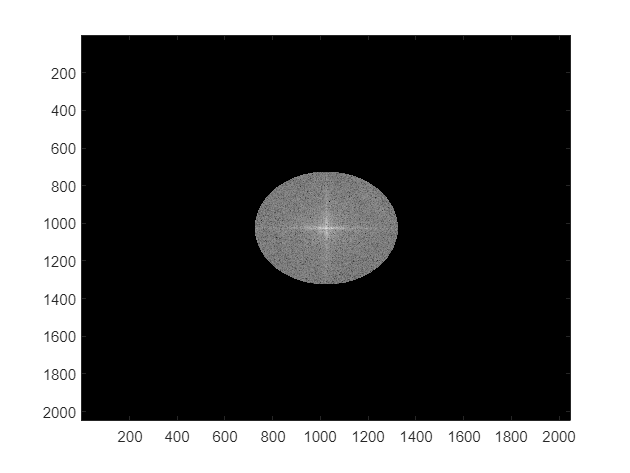

%Se traslada la imagen al centro para realizar la propagación
OrdenMasCentrado = imtranslate(OrdenMas,[1025-324, 1025-1469],'FillValues',0);
imagesc(log(abs(OrdenMasCentrado)))

%Se saca la transformada inversa del Orden Mas
IFFTCentroOrdenMas=(ifft2(OrdenMasCentrado));
imagesc(abs(IFFTCentroOrdenMenos))

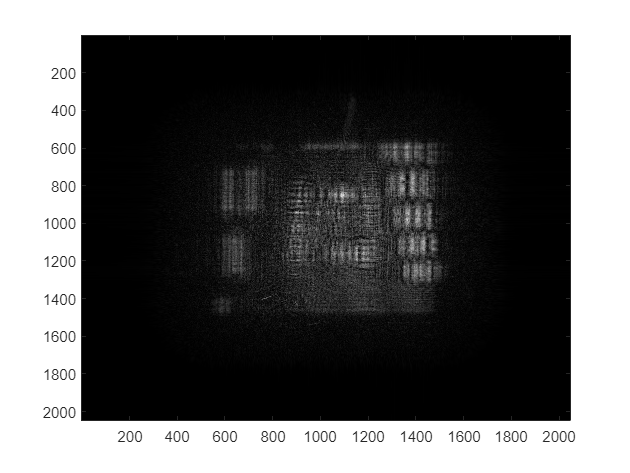

% Se realiza la propagación del orden menos centrado para encontrar la
% distribución de intensidad del objeto virtual

PropCentroOrdenMas=fftshift(transformadaFresnel(IFFTCentroOrdenMas,dx,dy,distPropagacion, lambda));
imagesc(abs((PropCentroOrdenMas)))

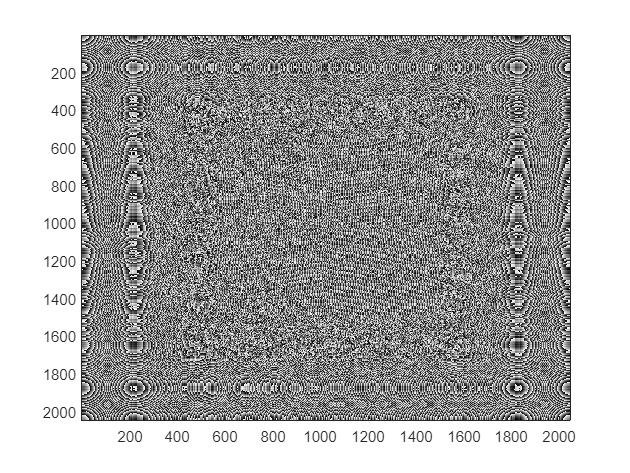

%Se visualiza la distribución de fase del objeto
imagesc(angle((PropCentroOrdenMenos)))